%same as 48
%Valida no drop
%4 pooling and conv
%3 classes
%balance: yes
%shortcut: yes
%shortcut num: 2
imageFiles = fullfile('origs');
imageDbs = imageDatastore(imageFiles);

classes = [
    "Glom"
    "Needle"
    "Background"
    ];
labelIDs = glomPixelLabelIDs();

labelFiles = fullfile('labels');
lableDbs = pixelLabelDatastore(labelFiles,classes,labelIDs);

%This is for test;
C = readimage(lableDbs,1)

C = 450×800 categorical array
  Columns 1 through 624

     Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background      Background  

tbl = countEachLabel(lableDbs);
frequency = tbl.PixelCount/sum(tbl.PixelCount);



newsize = [288 512]

newsize =    288   512


resizeOrigs = fullfile('resizeAddValOrig\',filesep);
imageDbs = resizeOrigImages(imageDbs,resizeOrigs, newsize);

resizeLables = fullfile('resizeAddValLable\',filesep);
lableDbs = resizeLabels(lableDbs,resizeLables, newsize);

[trainImages,testImages,trainLables,testLables] = partitionImages(imageDbs,lableDbs);

numTrainingImages = numel(trainImages.Files)

numTrainingImages = 260

numTestingImages = numel(testImages.Files)

numTestingImages = 112


imageSize = [288 512 3];
numClasses = numel(classes);
%use my network

%rebalance the classes
imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq;

lgraph = getMyNet(imageSize, 3, tbl.Name, classWeights);

dowsamplingLayers =   25x1 Layer array with layers:

     1   'con_1'         Convolution           64 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     2   'relu_1'        ReLU                  ReLU
     3   'batch_con_1'   Batch Normalization   Batch normalization
     4   'con_2'         Convolution           64 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu_2'        ReLU                  ReLU
     6   'batch_con_2'   Batch Normalization   Batch normalization
     7   'pool_1'        Max Pooling           2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   'con_3'         Convolution           128 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     9   'relu_3'        ReLU                  ReLU
    10   'batch_con_3'   Batch Normalization   Batch normalization
    11   'con_4'         Convolution           128 3x3 convolutions with

upsamplingLayers_1 =   6x1 Layer array with layers:

     1   'deCon_1'           Transposed Convolution   512 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     2   'relu_upSample_1'   ReLU                     ReLU
     3   'up_sample_1'       Batch Normalization      Batch normalization
     4   'deCon_2'           Transposed Convolution   128 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     5   'relu_upSample_2'   ReLU                     ReLU
     6   'up_sample_2'       Batch Normalization      Batch normalization

upsamplingLayers_2 =   3x1 Layer array with layers:

     1   'deCon_3'           Transposed Convolution   64 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     2   'relu_upSample_3'   ReLU                     ReLU
     3   'up_sample_3'       Batch Normalization      Batch normalization

upsamplingLayers_3 =   3x1 Layer array with layers:

     1   'deCon_4'           Transposed Convolution   64 4x4 transposed convolutions with stride [2  2] and output cropping [1  1]
     2   'relu_upSample_4'   ReLU                     ReLU
     3   'up_sample_4'       Batch Normalization      Batch normalization

combineLayers_1 =   3x1 Layer array with layers:

     1   'add_1'            Addition              Element-wise addition of 2 inputs
     2   'relu_combine_1'   ReLU                  ReLU
     3   'combine_1'        Batch Normalization   Batch normalization

combineLayers_2 =   3x1 Layer array with layers:

     1   'add_2'            Addition              Element-wise addition of 2 inputs
     2   'relu_combine_2'   ReLU                  ReLU
     3   'combine_2'        Batch Normalization   Batch normalization

finalLayers =   3x1 Layer array with layers:

     1   'conClass_1'   Convolution                  3 1x1 convolutions with stride [1  1] and padding [0  0  0  0]
     2   'softmax'      Softmax                      softmax
     3   'classify'     Pixel Classification Layer   Cross-entropy loss 

myNet =   47x1 Layer array with layers:

     1   'input'             Image Input                  288x512x3 images with 'zerocenter' normalization
     2   'con_1'             Convolution                  64 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu_1'            ReLU                         ReLU
     4   'batch_con_1'       Batch Normalization          Batch normalization
     5   'con_2'             Convolution                  64 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     6   'relu_2'            ReLU                         ReLU
     7   'batch_con_2'       Batch Normalization          Batch normalization
     8   'pool_1'            Max Pooling                  2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     9   'con_3'             Convolution                  128 3x3 convolutions with stride [1  1] and padding [1  1  1  1]
    10  

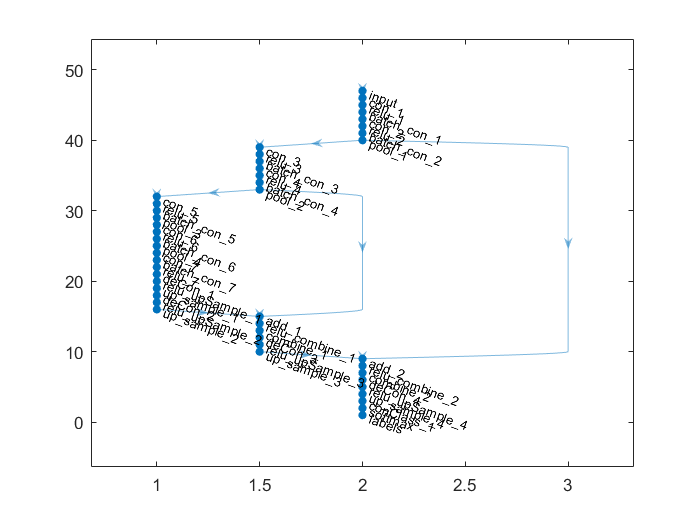

lgraph = layerGraph(lgraph);
lgraph = connectLayers(lgraph, 'pool_2', 'add_1/in2');
lgraph = connectLayers(lgraph, 'pool_1', 'add_2/in2');

pxLayer = pixelClassificationLayer('Name','labels','ClassNames',tbl.Name,'ClassWeights',classWeights);
lgraph = removeLayers(lgraph, 'classify');
lgraph = addLayers(lgraph, pxLayer);
lgraph = connectLayers(lgraph,'softmax','labels');

plot(lgraph)

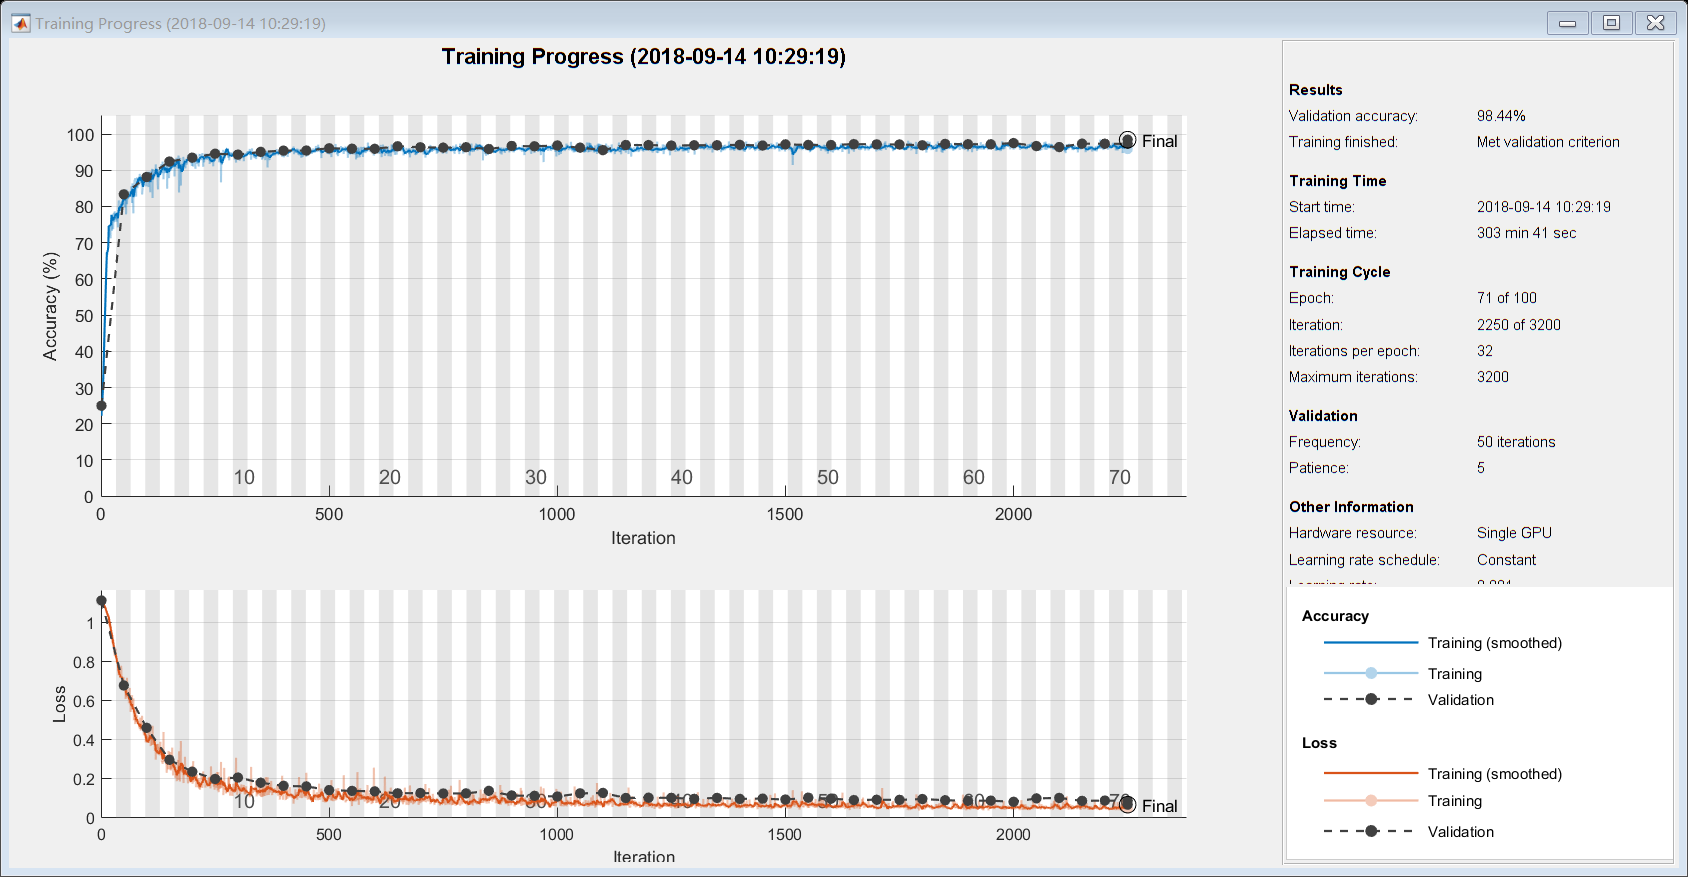

Training on single GPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:14 |       22.16% |       24.97% |       1.1122 |       1.1131 |          0.0010 |
|       1 |           2 |       00:00:40 |       24.49% |              |       1.1103 |              |          0.0010 |
|       1 |           4 |       00:00:58 |       29.34% |              |       1.0992 |              |          0.0010 |
|       1 |           6 |       00:01:15 |       38.42% |              |       1.0904 |              |          0.0010 |
|       1 |           8 |       00:01:32 |       48.51% |              |       1.0862 |              |          0.0010 |
|       1 |          10 |       00:01:49 |       56.22% |              |       1.0707 |              |          0.0010 |
|       1 |          12 |       00:02:05 |       64.17% |              |       1.0498 |              |          0.0010 |
|       1 |          14 |       00:02:21 |       66.66% |              |       1.0416 |              |          0.0010 |
|       1 |          16 |       





%make validation data
validata = pixelLabelImageDatastore(testImages, testLables);

options = trainingOptions('sgdm', ...
    'ValidationData',validata, ...
    'Plots', 'training-progress', ...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.0008, ...
    'MaxEpochs',100, ...
    'MiniBatchSize',8, ...
    'Shuffle','every-epoch', ...
    'VerboseFrequency',2);

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation',[-10 10],'RandYTranslation',[-10 10]);

pximds = pixelLabelImageDatastore(trainImages,trainLables,...
    'DataAugmentation',augmenter);

dotrain = true;
if dotrain
    
    [net, info] = trainNetwork(pximds,lgraph,options);
else
    data = load('net.mat');
    net = data.net;
end

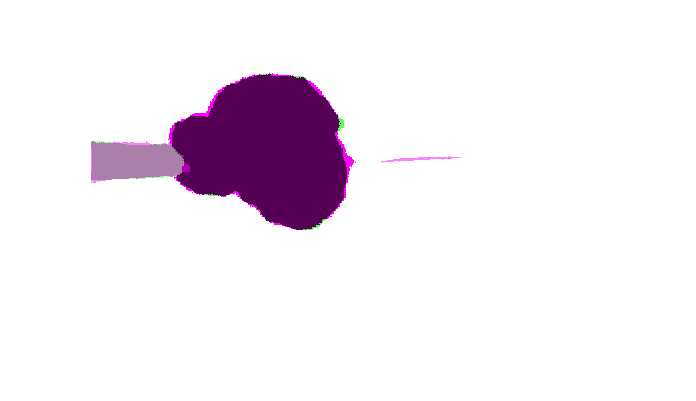


I = read(testImages);

C = semanticseg(I, net);
%I = histeq(I);
%imshow(I)

actual = uint8(C);
expectResult = read(testLables);
expect = uint8(expectResult);
imshowpair(actual, expect)


pxdsResults = semanticseg(testImages,net,'MiniBatchSize',4,'WriteLocation',tempdir,'Verbose',false);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


metrics = evaluateSemanticSegmentation(pxdsResults,testLables,'Verbose',false);
metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.98587          0.97736       0.9232       0.97129        0.90119  


metrics.ClassMetrics

ans = 3×3 table
                  Accuracy      IoU      MeanBFScore
                  ________    _______    ___________

    Glom          0.97291     0.91285      0.83364  
    Needle        0.97073     0.87214      0.91416  
    Background    0.98843      0.9846      0.95513  


function labelIDs = glomPixelLabelIDs()
% Return the label IDs.

labelIDs = { ...

% "Glom"
[
0 0 0; ... % "Glom"
]

% "Needle"
[
128 128 128; ... % "Needle"
]

% "Background"
[
255 255 255; ... % "Background"
]



};
end

function imds = resizeOrigImages(imds, imageFolder, newSize)
% Resize images to [36 48].

if ~exist(imageFolder,'dir')
    mkdir(imageFolder)
else
    imds = imageDatastore(imageFolder);
    return; % Skip if images already resized
end

reset(imds)
while hasdata(imds)
    % Read an image.
    [I,info] = read(imds);
    
    % Resize image.
    I = imresize(I,newSize);
    
    % Write to disk.
    [~, filename, ext] = fileparts(info.Filename);
    imwrite(I,[imageFolder filename ext])
end

imds = imageDatastore(imageFolder);
end



function pxds = resizeLabels(pxds, labelFolder, newSize)

classes = pxds.ClassNames;
labelIDs = 1:numel(classes);
if ~exist(labelFolder,'dir')
    mkdir(labelFolder)
else
    pxds = pixelLabelDatastore(labelFolder,classes,labelIDs);
    return; % Skip if images already resized
end

reset(pxds)
while hasdata(pxds)
    % Read the pixel data.
    [C,info] = read(pxds);
    
    % Convert from categorical to uint8.
    L = uint8(C);
    
    % Resize the data. Use 'nearest' interpolation to
    % preserve label IDs.
    L = imresize(L,newSize,'nearest');
    
    % Write the data to disk.
    [~, filename, ext] = fileparts(info.Filename);
    imwrite(L,[labelFolder filename ext])
end

labelIDs = 1:numel(classes);
pxds = pixelLabelDatastore(labelFolder,classes,labelIDs);
end

%This function modified from Matlab's documents.
function [imdsTrain, imdsTest, pxdsTrain, pxdsTest] = partitionImages(imds,pxds)
% Partition data by randomly selecting 70% of the data for training. The
% rest is used for validate.

rng(0);
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% 70% for training.
N = round(0.70* numFiles);
trainingIdx = shuffledIndices(1:N);

% other for testing.
testIdx = shuffledIndices(N+1:end);

% build datastores 
trainingImages = imds.Files(trainingIdx);
testImages = imds.Files(testIdx);
imdsTrain = imageDatastore(trainingImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = 1:numel(pxds.ClassNames);

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
testLabels = pxds.Files(testIdx);
pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end



function myNet = getMyNet(imageSize, classNum, className, classWeights)

imageLayer = imageInputLayer(imageSize, "Name", "input");

poolSize = 2;

%set upsampling layers
deConFilterSize = 4;

%set a pixel classification layer
classFilterSize = 1;

dowsamplingLayers = [
    convolution2dLayer(3, 64, 'Padding', 1, 'Name', 'con_1')
    reluLayer('Name','relu_1')
    batchNormalizationLayer('Name', 'batch_con_1')

    convolution2dLayer(3, 64, 'Padding', 1, 'Name', 'con_2')
    reluLayer('Name','relu_2')
    batchNormalizationLayer('Name', 'batch_con_2')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_1')
    
    convolution2dLayer(3, 128, 'Padding', 1, 'Name', 'con_3')
    reluLayer('Name','relu_3')
    batchNormalizationLayer('Name', 'batch_con_3')
    convolution2dLayer(3, 128, 'Padding', 1, 'Name', 'con_4')
    reluLayer('Name','relu_4')
    batchNormalizationLayer('Name', 'batch_con_4')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_2')
    
    convolution2dLayer(3, 256, 'Padding', 1, 'Name', 'con_5')
    reluLayer('Name','relu_5')
    batchNormalizationLayer('Name', 'batch_con_5')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_3')
    
    convolution2dLayer(3, 512, 'Padding', 1, 'Name', 'con_6')
    reluLayer('Name','relu_6')
    batchNormalizationLayer('Name', 'batch_con_6')
    maxPooling2dLayer(poolSize, 'stride', 2, 'Name', 'pool_4')
    
    convolution2dLayer(3, 1024, 'Padding', 1, 'Name', 'con_7')
    batchNormalizationLayer('Name', 'batch_con_7')
    reluLayer('Name','relu_7')
    ]

upsamplingLayers_1 = [
    transposedConv2dLayer(deConFilterSize, 512, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_1')
    reluLayer('Name','relu_upSample_1')
    batchNormalizationLayer('Name', 'up_sample_1')
    transposedConv2dLayer(deConFilterSize, 128, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_2')
    reluLayer('Name','relu_upSample_2') 
    batchNormalizationLayer('Name', 'up_sample_2')
    ]

upsamplingLayers_2 = [
    transposedConv2dLayer(deConFilterSize, 64, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_3')
    reluLayer('Name','relu_upSample_3')
    batchNormalizationLayer('Name', 'up_sample_3')
    ]

upsamplingLayers_3 = [
    transposedConv2dLayer(deConFilterSize, 64, 'Stride', 2, 'Cropping', 1, 'Name', 'deCon_4')
    reluLayer('Name','relu_upSample_4')
    batchNormalizationLayer('Name', 'up_sample_4')
    ]

combineLayers_1 = [
    additionLayer(2, 'Name', 'add_1')
    reluLayer('Name','relu_combine_1')
    batchNormalizationLayer('Name', 'combine_1')
    ]

combineLayers_2 = [
    additionLayer(2, 'Name', 'add_2')
    reluLayer('Name','relu_combine_2')
    batchNormalizationLayer('Name', 'combine_2')
    ]

 
%compare with segTest5, here, the weight of each class are considered.
finalLayers = [
    convolution2dLayer(classFilterSize, classNum, 'Name', 'conClass_1')
    softmaxLayer('Name', 'softmax')
    %pixelClassificationLayer('Name','newClassify','ClassNames',className,'ClassWeights',classWeights)
    pixelClassificationLayer('Name', 'classify')
    
    ]

myNet = [
    imageLayer
    dowsamplingLayers
    upsamplingLayers_1
    combineLayers_1
    upsamplingLayers_2
    combineLayers_2
    upsamplingLayers_3
    finalLayers
    ]
end